clear all;

B_1 = 0.015;
B_2 = 0.0015;
J_1 = 0.0022;
J_2 = 0.000545;
B_3 = B_2;
J_3 = J_2;
K_s1 = 1;
K_s2 = K_s1;

k_t = 0.00767;
k_m = 0.00767;
R_m = 2.6;
nu_m = 0.69;
nu_g = 0.85;
K_gi = 14;
K_ge_low = 1;
K_ge_high = 5;
K_g = (K_gi*K_ge_low*K_ge_high);

H = nu_g*K_g*nu_m*k_t

H = 0.3149

J = K_g*k_m

J = 0.5369


theta_1_dot_const = -(H*J)/(J_1*R_m)-B_1/J_1;

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     -K_s1/J_1 K_s1/J_1 0 theta_1_dot_const 0 0;
     K_s1/J_2 -(K_s1+K_s2)/J_2 K_s2/J_2 0 -B_2/J_2 0;
     0 K_s2/J_3 -K_s2/J_3 0 0 -B_3/J_3];
B = [0; 0; 0; H/(J_1*R_m); 0; 0];
C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];
D = 0;

x_0 = [0;0;0;0;0;0];

sys = ss(A, B, C, D);
Ts = 0.001;
sys_d = c2d(sys, Ts);

P_0 = eye(6);
x_kalman = [2;1;3;2;3;1];
An = sys_d.A;
Bn = sys_d.B;
Ln = [0 ; 0;0;0;0;1*Ts];
Hn = sys_d.C;
Q_n = 4000;
R_n = [1e-3 0 0;
       0 1e-3 0;
       0 0 1e-3];
V_m_max = 6;

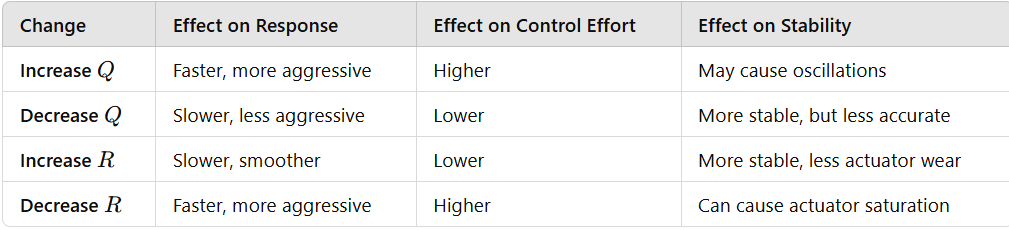

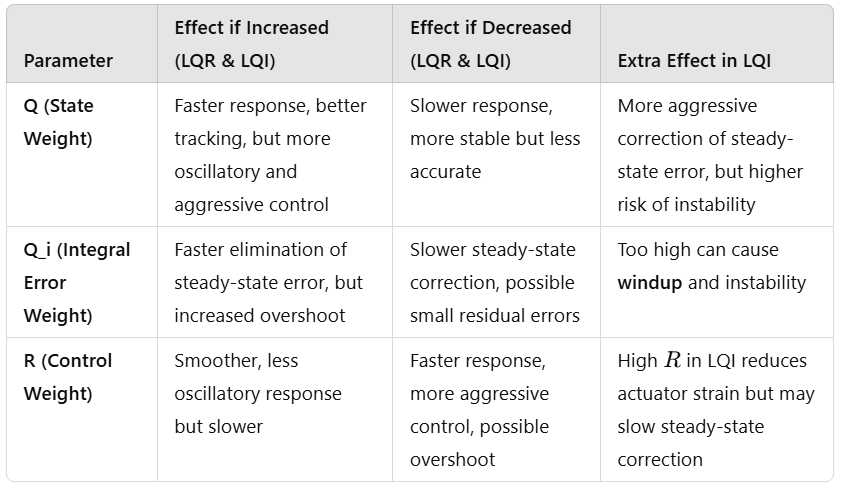

% LQR tuning using Bryson's rule:
R_lqr = 1/V_m_max^2;
Q_lqr = zeros(6,6);
Q_lqr(1,1) = 1/((10/(2*pi))^2);
Q_lqr(2,2) = 1/((10/(2*pi))^2);
Q_lqr(3,3) = 1/((10/(2*pi))^2);
Q_lqr(4,4) = 1/((1)^2);
Q_lqr(5,5) = 1/((1)^2);
Q_lqr(6,6) = 1/((1)^2);

Q_lqr = Q_lqr; % high Q faster convergance, but higher overshoot and higher actuator effort
R_lqr = R_lqr; % Low R less overshoot

K_lqr = lqr(A, B, Q_lqr, R_lqr)

K_lqr =   289.2750 -341.9339   59.1886    6.1910    2.5920    0.3713


eig(A-B*K_lqr)

ans = 	1.0e+02 *

  -3.3099 + 0.0000i
  -0.1079 + 0.7006i
  -0.1079 - 0.7006i
  -0.0063 + 0.0000i
  -0.1475 + 0.3071i
  -0.1475 - 0.3071i


% LQI tuning:
% we have 2 more states Q = 2x2 => Q = 4x4
Q_i = diag([1/(0.8)^2, 1/(0.8)^2]); % Assuming max steady-state error of 0.01m
sys = ss(A,B,C,D);
Q_lqi = blkdiag(Q_lqr, Q_i);
R_lqi = R_lqr;
K_lqi = lqi(sys,Q_lqi,R_lqi)

Error using ss/lqi (line 67)
The Q matrix must be square of size 9.